# **IO106 - Analog Input Test**

This example shows you how to perform a test with the IO106 I/O module to verify the analog input functionality of some of the input channels in differential mode.

The IO106 is a 16-bit analog module that can offer either 64 or 32 simultaneous sampling analog input channels. The input coupling mode is software selectable between **Single-ended**, **Pseudo-Differential** and **Differential**. The number of analog input channels varies depending on the selected mode.  

The Simulink model used in this example features the [IO106 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io106_setup) and [IO106 Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io106_analog_input) blocks.

## Test Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO106 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

- External signal generator

### Wiring

When the **Single-ended** **Input Coupling** is used, the analog input signal is measured between the input pin and the common input return pin **Input RTN**. The **Pseudo-differential** mode measures the voltage difference between the input pin and a common reference level that is applied on the **Input (-) (remote sense)** channel available on pin 1 for all variants. In **Differential Input Coupling** mode, two pins are available for each analog input channel to measure the voltage difference between the two inputs. One pin is used for the positive reference (+) and one pin for the negative reference (-).

This example can be used as a test for analog inputs, where the differential inputs are connected to an external signal generator. 

The following wiring is required:

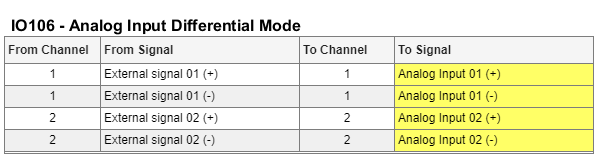

The full pin mapping of the IO106 can be found here: [IO106 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io106_pin_mapping)

## Open Simulink Model

 
modelName = 'sgMdl_IO106_AnalogInputTest';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the Simulink scope connected to the [IO106 Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io106_analog_input) block and check if the signals displayed correspond to the signals created by the external signal generator. Two signals must be displayed. The screenshot below is an example of two sine wave signals with different amplitudes. 

  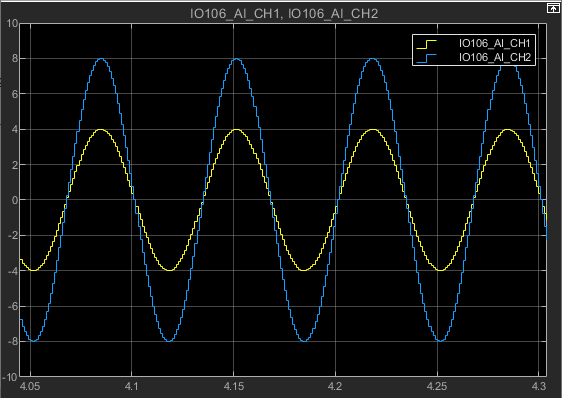

## Additional References

- [IO106 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io106)